x1=5;
x2=7;
x3=11;
x4=13;
L=16;
h=3;

n=5

n = 5

nn=[1:1:n]

nn =      1     2     3     4     5



syms x
syms sn
f= piecewise(x<x1|x>=x4,0,x>=x1&x<x2,(h/(x2-x1))*(x-x1),x>=x2&x<x3,h,x>=x3&x<x4,(-h/(x4-x3))*(x-x4))

$$f = \left\{ \begin{array}{cl} 0 & \text{ if }x<5\vee 13\leq x\\ \frac{3\,x}{2}-\frac{15}{2} & \text{ if }x\in \left[5,7\right)\\ 3 & \text{ if }x\in \left[7,11\right)\\ \frac{39}{2}-\frac{3\,x}{2} & \text{ if }x\in \left[11,13\right) \end{array}\right.$$

a0=(1/L)*int(f,-L,L)

$$a0 = \frac{9}{8}$$



xx=linspace(0,L,1000);
fpl=subs(f,x,xx);
plot(xx,fpl)
f*cos(pi*sn*x/L);
a = (1/L)*int(f*cos(pi*sn*x/L),x,-L,L);
aa=subs(a,sn,nn);
aa=double(aa)

aa =    -0.2057   -0.7943    0.3272    0.2149   -0.0525


%aa=[-0.0662,-0.7415,0.0764,0.3085]
b = (1/L)*int(f*sin(pi*sn*x/L),x,-L,L);
bb=subs(b,sn,nn);
bb=double(bb)

bb =     1.0340   -0.3290   -0.4897    0.2149    0.0351


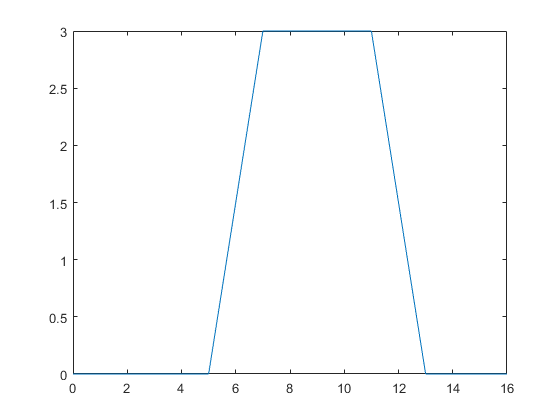

%bb=[0.9081,-0.0986,-0.5223,0.0154]
ffou=(a0/2)+sum(aa.*cos(pi.*nn.*x./L)+bb.*sin(pi.*nn.*x./L),0);
hold on

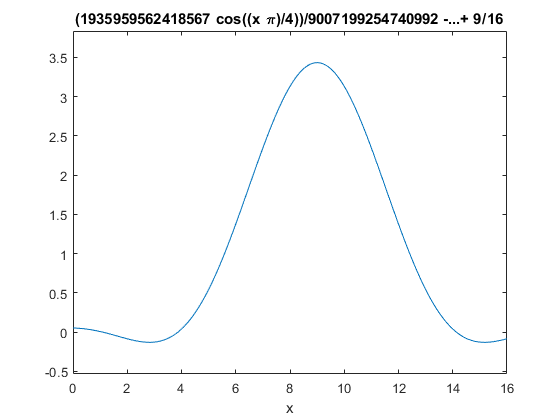


ezplot(ffou,0,L)

p = (1/L)*int((f*f),x,-L,L)

$$p = 3$$

pp=a0/2+sum(aa.^2.+bb.^2)

$$pp = \frac{3215894038225581}{1125899906842624}$$

double(pp)

ans = 2.8563

b = (2/L)*int(f*sin(pi*sn*x/L),x,0,L);
bb=subs(b,sn,nn);
bb=double(bb)

bb =     2.0680   -0.6580   -0.9793    0.4299    0.0701


p1 = (2/L)*int((f*f),x,0,L)

$$p1 = 6$$

pp1=sum(bb.^2)

pp1 = 5.8583

double(pp1)

ans = 5.8583

%ezplot(xx,yy)